clc; clear; close all;

% Define the number of floors in the building
n = 10; % Change the number of floors

Mahanakhon has 79 floors and its weight of 1600 MN

[https://www.afgc.asso.fr/app/uploads/2016/10/09-Design-and-construction-of-the-Mahanakhon-tower-in-Bangkok.pdf?utm_source=chatgpt.com](https://www.afgc.asso.fr/app/uploads/2016/10/09-Design-and-construction-of-the-Mahanakhon-tower-in-Bangkok.pdf?utm_source=chatgpt.com)

% Building Dimension and Properties
floor_w = 40; floor_l = 40; g = 9.81;
floor_mass = round(1600E6/g/79);

Assume the steel yield stength is 500 MPa and Concrete partial material safety factor equal 1.5 Modulus of elasticity round up around 30000 MPa or 30 GPa

[https://eurocodeapplied.com/design/en1992/concrete-design-properties](https://eurocodeapplied.com/design/en1992/concrete-design-properties)

Mahanakhon Building has 12 Mega Column, and RC core wall of 23*23 m. In this simulated, we will not consider only RC core wall as a main stiffness.

[https://www.dextragroup.com/mahanakhon-tower/](https://www.dextragroup.com/mahanakhon-tower/)

[https://www.scribd.com/document/338577575/306175551-Concept-Design-Report-Mahanakhon-Building-pdf?utm_source=chatgpt.com](https://www.scribd.com/document/338577575/306175551-Concept-Design-Report-Mahanakhon-Building-pdf?utm_source=chatgpt.com)

E = 30e9; % Elastic modulus in Pascals (Pa)
Mass = floor_mass * ones(n,1)'; % Masses of each floor in kg
Height = 4 * ones(n,1)'; % Heights of each floor in meters
Inertia = 1.5^4/12 * ones(n,1); % Moment of inertia in m^4

% Calculate the stiffness for each floor using the formula k = 12EI/h^3
k_values = 12 * 12 * E * Inertia ./ Height.^3; % Four Spring In Each Floor


$$\mathit{\mathbf{M}}=\left\lbrack \begin{array}{ccccccc}
m_1  & 0 & 0 & \cdots  & 0 & 0 & 0\\
0 & m_2  & 0 & \cdots  & 0 & 0 & 0\\
0 & 0 & m_3  & \cdots  & 0 & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots  & \vdots \\
0 & 0 & 0 & \cdots  & m_8  & 0 & 0\\
0 & 0 & 0 & \cdots  & 0 & m_9  & 0\\
0 & 0 & 0 & \cdots  & 0 & 0 & m_{10} 
\end{array}\right\rbrack$$


$\mathit{\mathbf{K}}$=$\left\lbrack \begin{array}{ccccccc}
k_1 +k_2  & {-k}_2  & 0 & 0 & \cdots  & 0 & 0\\
-k_2  & k_2 +k_3  & -k_3  & 0 & \cdots  & 0 & 0\\
0 & -k_3  & k_3 +k_4  & -k_4  & \cdots  & 0 & 0\\
0 & 0 & -k_4  & k_4 +k_5  & \cdots  & 0 & 0\\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & 0 & -k_9  & k_9 +k_{10}  & -k_{10} \\
0 & 0 & 0 & 0 & 0 & -k_{10}  & k_{10} 
\end{array}\right\rbrack$

M = diag(Mass);
K = zeros(n);
for i = 1:n-1
    K(i,i) = k_values(i) + k_values(i+1);
    K(i,i+1) = -k_values(i+1);
    K(i+1,i) = -k_values(i+1);    
end
K(n,n) = k_values(n);

Finding Natural Frequency for Assuming the Rayleigh Damping Coefficients


$$\mathbf{M}\overset{\cdot \cdot }{\mathbf{X}} +\textrm{KX}=0$$


[U,D] = eig(K,M);
w1 = D(1,1); w2 = D(2,2);


$$\mathbf{C}=\alpha \mathbf{M}+\beta \mathbf{K}$$


$\zeta =\frac{1}{2}\left(\frac{\alpha }{\omega }+\beta \omega \right)$ ;  Rayleigh Damping Coefficients

[https://www.orcina.com/webhelp/OrcaFlex/Content/html/Rayleighdamping,Guidance.htm](https://www.orcina.com/webhelp/OrcaFlex/Content/html/Rayleighdamping,Guidance.htm)

syms alpha beta
% Give damping ration = 5%
eq1 = 0.05 == 0.5*(alpha/w1 + beta*w1);
eq2 = 0.05 == 0.5*(alpha/w2 + beta*w2);
[a,b] = solve(eq1,eq2);
a = vpa(a)

$$a = 27.68876706408824368131489359933$$

b = vpa(b)

$$b = 0.000032894521560077955830320103241098$$


$$\mathbf{M}\overset{\cdot \cdot }{\mathbf{X}} +\mathbf{C}\overset{\cdot }{\mathbf{X}} +\textrm{KX}=-\textrm{M1}\overset{,,}{{\mathbf{u}}_{\mathbf{g}} } \left(\mathbf{t}\right)$$


where x is relative displacement of each floor with respect to ground

% M_c = 2967781623447.234403808909534589 * M; 
% K_c = 1.0000000000000003068988425448726 * K;
[U,D] = eig(K,M);
omega_n = sqrt(diag(D));
x_0 = zeros(n,1); % initial condition
v_0 = zeros(n,1); % initial condition
r_0 = U'*M*x_0;
rdot_0 = U'*M*v_0;
R_i = [r_0 rdot_0];

% Check
%U'*M*U should be I
%U'*K*U should be w^2 (sprectal matrix)
% Print results to the MATLAB console
fprintf('Stiffness matrix [K] in N/m:\n');

Stiffness matrix [K] in N/m:


disp(K);

   1.0e+10 *

    5.6953   -2.8477         0         0         0         0         0         0         0         0
   -2.8477    5.6953   -2.8477         0         0         0         0         0         0         0
         0   -2.8477    5.6953   -2.8477         0         0         0         0         0         0
         0         0   -2.8477    5.6953   -2.8477         0         0         0         0         0
         0         0         0   -2.8477    5.6953   -2.8477         0         0         0         0
         0         0         0         0   -2.8477    5.6953   -2.8477         0         0         0
         0         0         0         0         0   -2.8477    5.6953   -2.8477         0         0
         0         0         0         0         0         0   -2.8477    5.6953   -2.8477         0
         0         0         0         0         0         0         0   -2.8477    5.6953   -2.8477
         0         0         0         0         0         0         0       


fprintf('Mass matrix [M] in kg:\n');

Mass matrix [M] in kg:


disp(M);

     2064543           0           0           0           0           0           0           0           0           0
           0     2064543           0           0           0           0           0           0           0           0
           0           0     2064543           0           0           0           0           0           0           0
           0           0           0     2064543           0           0           0           0           0           0
           0           0           0           0     2064543           0           0           0           0           0
           0           0           0           0           0     2064543           0           0           0           0
           0           0           0           0           0           0     2064543           0           0           0
           0           0           0           0           0           0           0     2064543           0           0
           0           0        


Lambda = char(hex2dec('039B'));                     
fprintf(['Sprectal Matrix [' Lambda '] \n']);

Sprectal Matrix [Λ] 


disp(U'*K*U);

   1.0e+04 *

    0.0308   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.2732   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.7364   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.3793    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000    2.1448   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000    2.9648   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    3.7665   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    4.4786    0.0000    0.0000
    0.0000         0    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    5.0379   -0.0000
         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0

Mode Shape Visualize

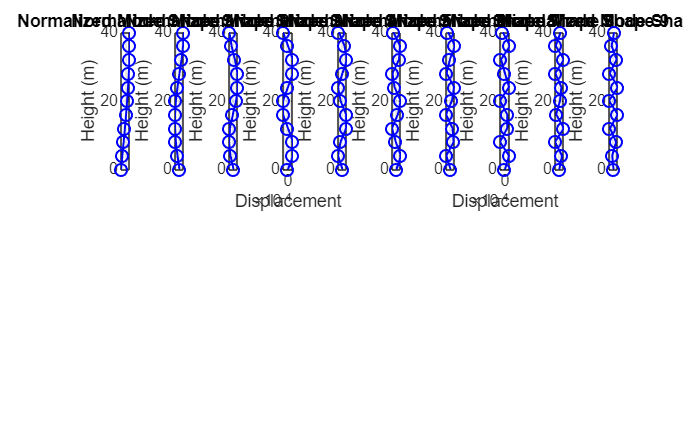

heights = [0, cumsum(Height)];
for i = 1:n
    subplot(2, n, i);
    plot([0; U(:,i)], heights, 'o-','Color', 'b', 'LineWidth',1);
    title(['Normalized Mode Shape ', num2str(i)]);
    xlabel('Displacement');
    ylabel('Height (m)');
    grid on;
    axis tight;
end
% Optional: Maximize figure window for better visibility
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

Modal Analysis of Based Excitation

a = 27.68876706408824368131489359933;
b = 0.000032894521560077955830320103241098;
% There are some problems with type of matrix C
C = a*M + b*K;
M_modal = U' * M * U; % Should be identity matrix
C_modal = U' * C * U;
K_modal = U' * K * U % Should be spectral matrix

K_modal = 1.0e+04 *

    0.0308   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.2732   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.7364   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.3793    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000    2.1448   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000    2.9648   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    3.7665   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    4.4786    0.0000    0.0000
    0.0000         0    0.0000         0   -0.0000   -0.0000    0.0000    0.0000    5.0379   -0.0000
         0         0   -0.0000    0.0000   -0.0000   -0.0000   -0.0000


$$\mathbf{M}\overset{\cdot \cdot }{{\mathbf{x}}_{\mathbf{r}} } \left(\mathbf{t}\right)+\mathbf{C}\overset{\cdot }{{\mathbf{x}}_{\mathbf{r}} } \left(\mathbf{t}\right)+{\textrm{Kx}}_{\mathbf{r}} \left(\mathbf{t}\right)=-\mathbf{M}\overset{\cdot \cdot }{\mathbf{y}}$$


Given ${\mathrm{X}}_{\mathrm{r}\;} =\textrm{Ur}$


$$\overset{\cdot \cdot }{{\mathbf{r}}_{\mathbf{i}} } \left(\mathbf{t}\right)+2\zeta \omega_{\mathbf{n},\mathbf{i}} \overset{\ldotp }{{\mathbf{r}}_{\mathbf{i}} } \left(\mathbf{t}\right)+\omega_{\mathbf{n},\mathbf{i}\;}^2 \mathbf{r}\left(\mathbf{t}\right)={\mathbf{N}}_{\mathbf{i}\;} \left(\mathbf{t}\right)\;;\mathbf{N}\left(\mathbf{t}\right)=-{\mathbf{U}}^{\mathrm{T}} \mathbf{M}\overset{\ldotp \ldotp }{\mathbf{y}} \left(\mathbf{t}\right)$$


where $2\zeta \omega_{\mathrm{n},\mathrm{i}} =\alpha +\beta \omega_{\mathrm{n},\mathrm{i}\;}^2 ={\mathrm{U}}^{\mathrm{T}} \textrm{CU}\;$and $\Gamma =$${-\mathbf{U}}^{\mathbf{T}} \textrm{M1}$

% Earthquake
w = 52;
f = 2*pi*w;
fs = 2.5*f; %Sampling Frequency
t_end = 30;
number_of_t = t_end * fs;
tspan = linspace(0,t_end,number_of_t);
y = 0.2 * sin(w*tspan);
ay = 0.2 * w^2 * sin(w*tspan);
r = zeros(n,length(tspan));
gamma = -U'* M * ones(n,1);
for i = 1:n
    omega_i = omega_n(i);
    zw_i = a + b * omega_i^2;
    gamma_i = gamma(i);
    eom_ode = @(t, r) eom(t,r,omega_i,zw_i,gamma_i,w);
    r_i = R_i(i,:); % Initial conditions: [r_i(0); rdot_i(0)]  
    [t, y] = ode45(eom_ode, tspan, r_i);
    r(i,:) = y(:,1)';
end

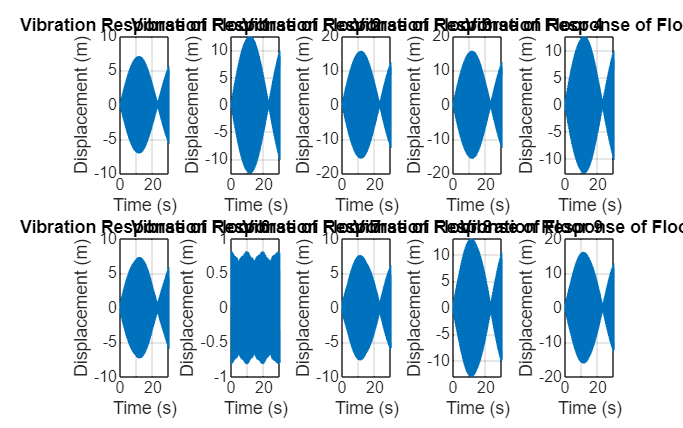

x = U*r;
xg = 0.2 * sin(w*tspan); % Subject to change by excitation
x = x + xg; %Change from relative displacement to absolute

%Plot response of each floor in subplots
figure;

for floor = 1:n
    subplot(2, n/2, floor);
    plot(t, x(floor, :), 'LineWidth', 0.5);
    title(['Vibration Response of Floor ', num2str(floor)]);
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    grid on;
end
% Optional: Maximize figure window for better visibility
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

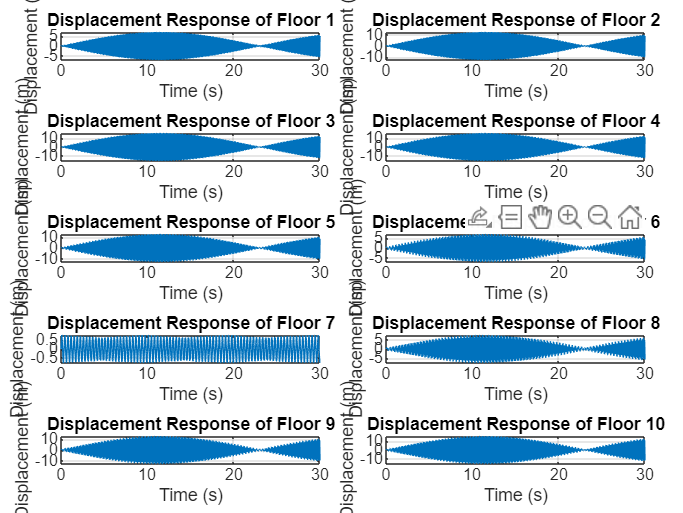


%Plot response of each floor in subplots
figure;
tiledlayout(5,2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:n
    nexttile;
    plot(t, x(i, :));
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    title(['Displacement Response of Floor ', num2str(i)]);
    grid on;
    axis tight;
end

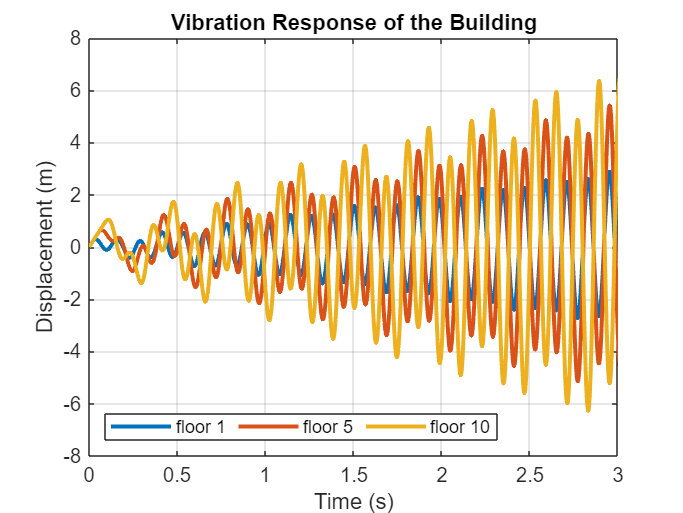

%All Floor Plot in 1 Graph
figure;
for floor = [1,5,10]
    plot(t, x(floor, :),LineWidth=2);
    grid on;
    hold on
end
title(['Vibration Response of the Building']);
xlabel('Time (s)');
ylabel('Displacement (m)');
xlim([0 3]);
legend({'floor 1','floor 5','floor 10'} ...
    ,'Location','southwest','Orientation','horizontal')

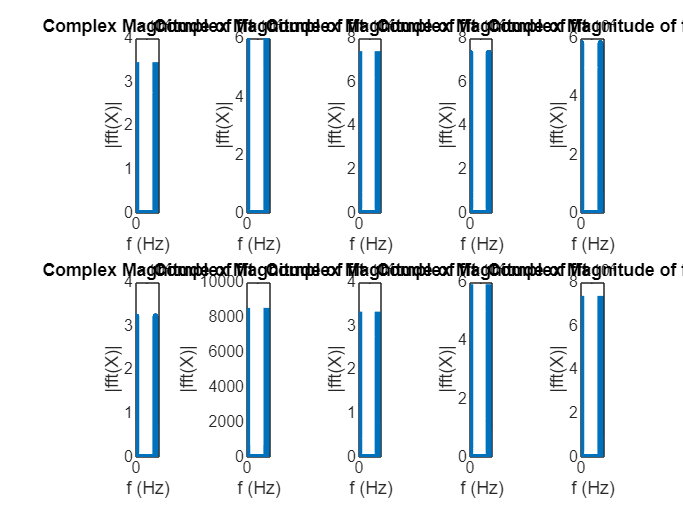

%FFT
figure;
for floor = 1:n                
    T = 1/fs;   % Sampling period  
    L = length(t);
    t = (0:L-1)*T; % Time vector
    subplot(2, n/2, floor);
    N = length(x);  
    fs = 1/(t(2) - t(1));  % Sampling frequency
    f = (0:N-1)*(fs/N);  % Frequency vector in Hz
    omega = 2 * pi * f;  % Convert to ω (rad/s)
    Y = fft(x(floor,:));
    plot(fs/L*(0:L-1),abs(Y),"LineWidth",3)
    title("Complex Magnitude of fft")
    xlabel("f (Hz)")
    ylabel("|fft(X)|")
end

Vibration Suppression

% %% ---------- CASE 1: TMD only (adds 1 DOF) ----------
% ma = 1E6; % TMD mass
% ka = 2.89E8; % Tuned to w = 15 rad/s
% 
% M1 = blkdiag(M, mt);
% K1 = blkdiag(K, 0);
% C1 = blkdiag(C, 0);
% 
% K1(n,n) = K1(n,n) + kt;
% K1(n+1,n+1) = kt;
% K1(n,n+1) = -kt;
% K1(n+1,n) = -kt;
% 
% C1(n,n) = C1(n,n) + ct;
% C1(n+1,n+1) = ct;
% C1(n,n+1) = -ct;
% C1(n+1,n) = -ct;

Vibration Absorber

function rdot = eom(t,r,omega_i,zw_i,gamma_i,w)
    ay = -0.2 * w^2 * sin(w*t);
    rdot = zeros(2,1);
    rdot(1) = r(2);
    rdot(2) = -zw_i*rdot(2) - omega_i^2*r(1) + gamma_i*ay;
end